# Contrasts of cue and stim

Model (CESO)

parameter:

- `C``ue: onset01_cue`

- `E``xpect rating: onset02_ratingexpect, pmod_expectRT`

- `S``timulus: onset03_stimulus`

- `O``utcome rating: onset04_ratingoutcome, pmod_outcomeRT`

- Motion covariate: 24DOF + CSF

- Spike, as many spikes detected by fmriprep (FD spike threshold 0.9)

## Pain > (Vicarious & Cognitive)

#### Pain > VC :: load dataset

contrast_of_interest = 'stim_P';

nifti_save_dir = '/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model02_CESO/2ndlevel';
nifti_save_fname_prefix = 'model02-CESO_epoch-stim';

mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESO/1stlevel';
contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C'
};

index = find(strcmp(contrast_name, contrast_of_interest));
con_name = sprintf('*con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 38736756 bytes
Loading image number:    97
Elapsed time is 4.001960 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 9214460  Bit rate: 23.14 bits


#### Pain > VC :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

SPM12: spm_check_registration (v7759)              23:25:12 - 21/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


#### Pain > VC :: Plot diagnostics, before l2norm

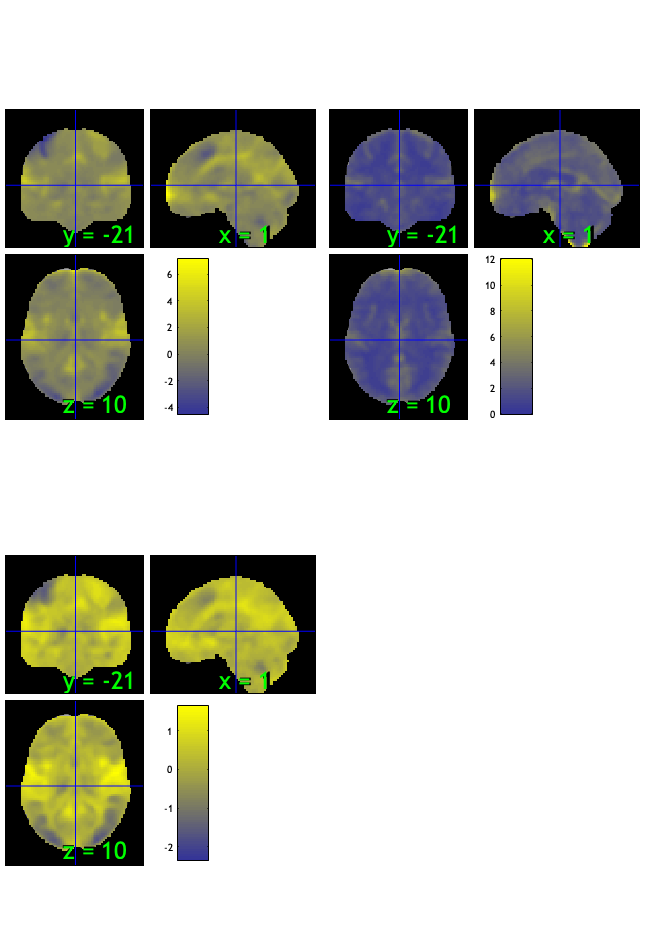

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 2 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 30.93%
Expected 4.85 outside 95% ellipsoid, found   8

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 2 images		Cases 23 24 
Uncorrected: 8 images		Cases 1 5 9 11 23 24 25 81 

Retained 5 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 44.33%
Expected 4.85 outside 95% ellipsoid, found   4

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 4 images		Cases 5 47 68 69 

Mahalanobis (cov and corr, q<0.05 corrected):
  2 images 
                               Outlier_count    Percentage
                           

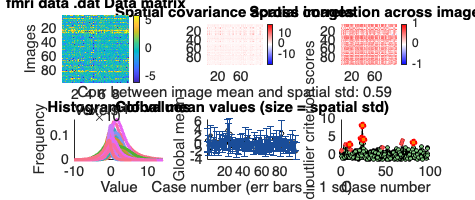

SPM12: spm_check_registration (v7759)              23:25:38 - 21/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

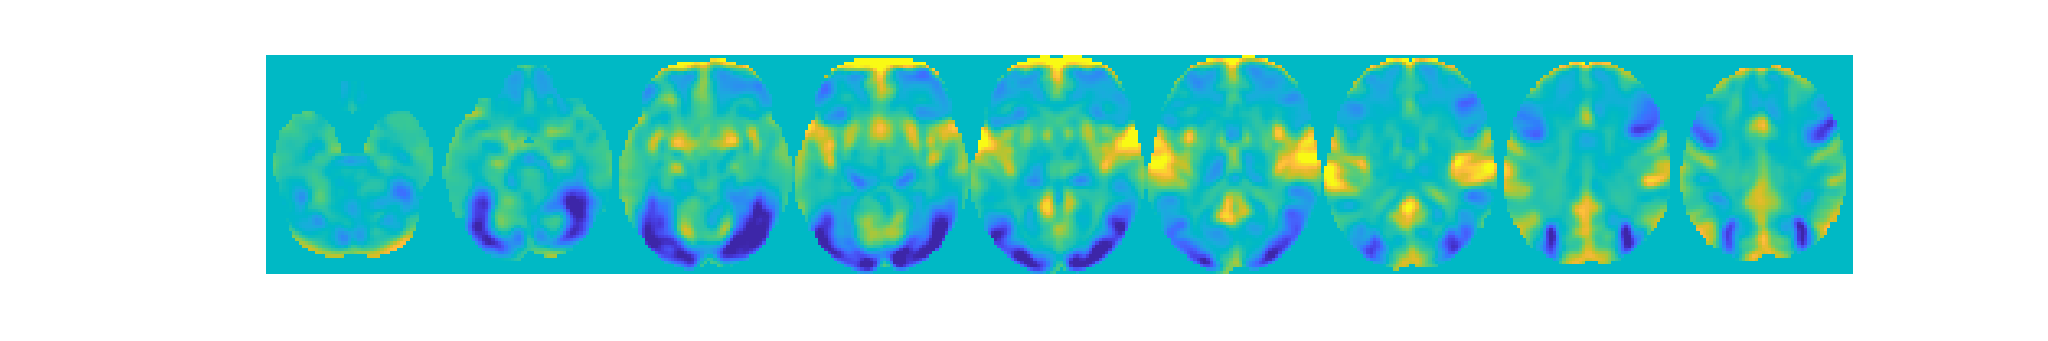

wh_outlier_uncorr = 97×1 logical array
   1
   0
   0
   0
   1
   0
   0
   0
   1
   0


wh_outlier_corr = 97×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0


drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj)

#### Pain > VC :: run robfit

set(gcf,'Visible','on')
figure ('Visible', 'on');
drawnow, snapnow;

#### Pain > VC :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))))

current length is 97


%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×92 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [92×21 char]
              fullpath: [97×112 char]
           files_exist: [97×1 logical]
               history:

con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×92 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [92×21 char]
              fullpath: [92×112 char]
           files_exist: [97×1 logical]
               history:

con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×92 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [92×21 char]
              fullpath: [92×112 char]
           files_exist: [92×1 logical]
               history:

%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

after removing 5 participants, size is now 92


#### Pain > VC :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Pain > VC :: ttest

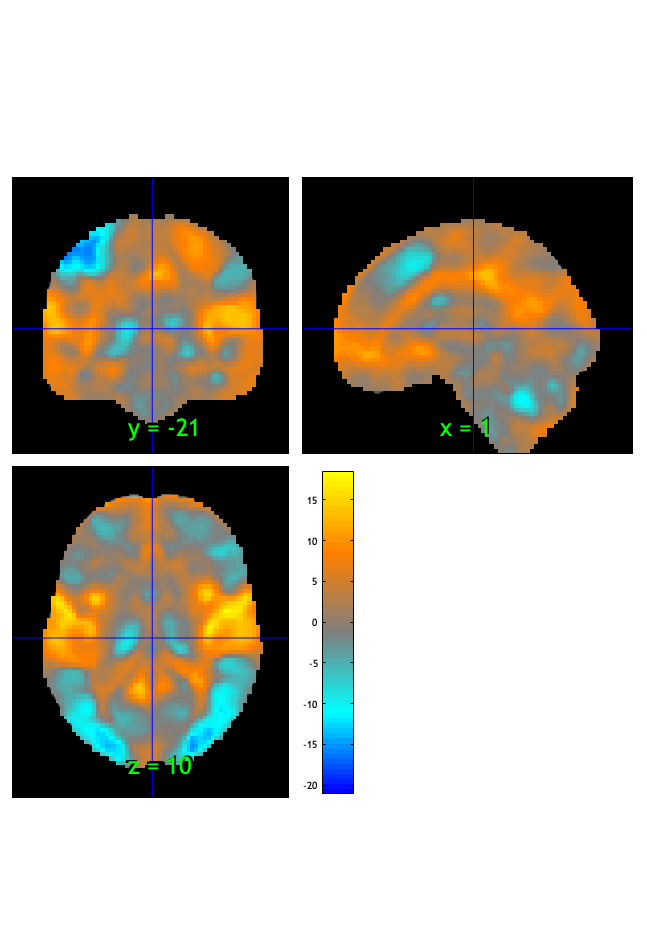

One-sample t-test
Calculating t-statistics and p-values


SPM12: spm_check_registration (v7759)              23:25:41 - 21/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Image   1 FDR q < 0.050 threshold is 0.032597

Image   1
 19 contig. clusters, sizes   1 to 64974
Positive effect: 36945 voxels, min p-value: 0.00000000
Negative effect: 28158 voxels, min p-value: 0.00000000


SPM12: spm_check_registration (v7759)              23:25:42 - 21/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


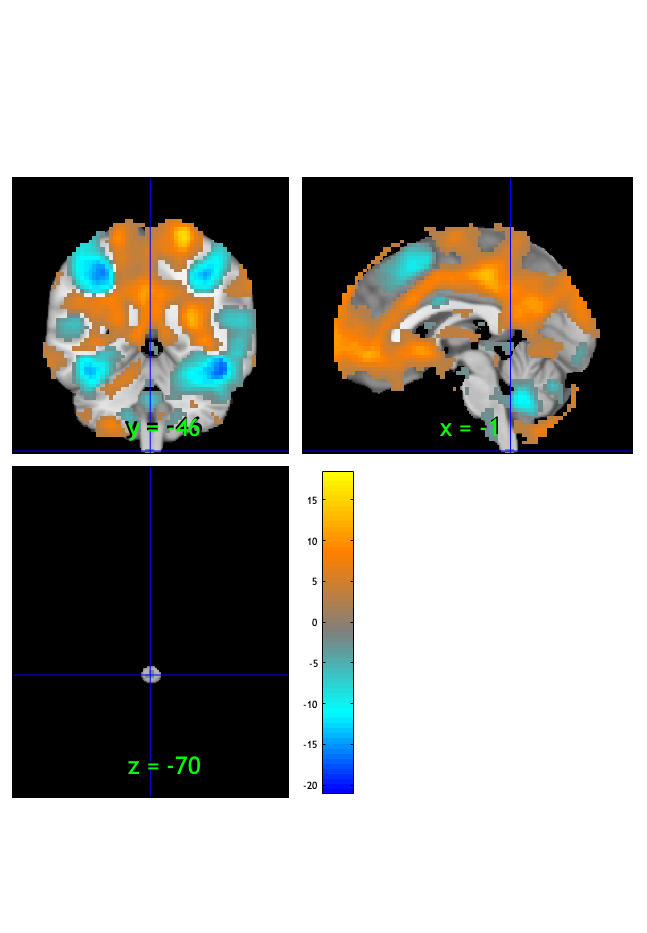

Image   1 FDR q < 0.001 threshold is 0.000468

Image   1
 24 contig. clusters, sizes   1 to 46186
Positive effect: 25746 voxels, min p-value: 0.00000000
Negative effect: 20934 voxels, min p-value: 0.00000000


SPM12: spm_check_registration (v7759)              23:25:43 - 21/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


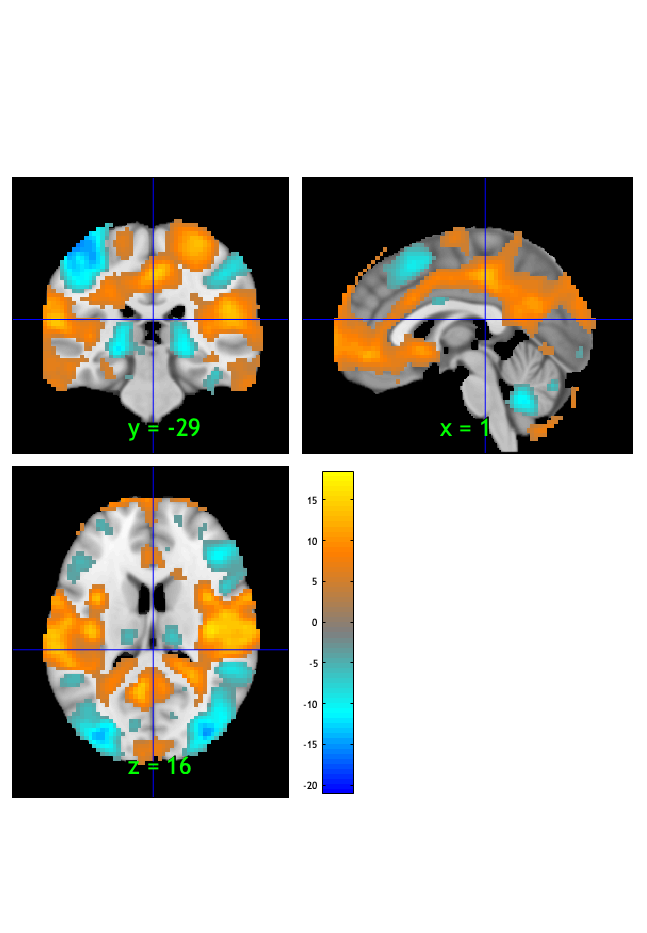

Setting up fmridisplay objects
sagittal montage: 970 voxels displayed, 45710 not displayed on these slices
sagittal montage: 960 voxels displayed, 45720 not displayed on these slices
sagittal montage: 929 voxels displayed, 45751 not displayed on these slices
axial montage: 8680 voxels displayed, 38000 not displayed on these slices
axial montage: 9533 voxels displayed, 37147 not displayed on these slices


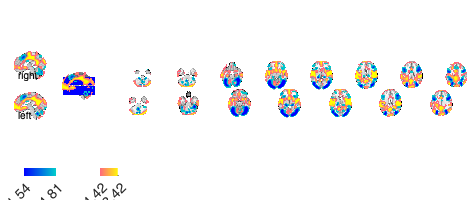

Writing: 
/Users/h/Desktop/stim_P_fdr_t.nii


t = ttest(imgs2);

orthviews(t);
drawnow, snapnow;

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low       words_low       testr_high      words_high   
    _________    _______________    __________    _______________

    -0.51563     {'visual'     }     0.35252      {'rating'     }
    -0.46315     {'object'     }     0.35015      {'sensation'  }
    -0.43096     {'objects'    }     0.34947      {'pain'       }
    -0.34817     {'shape'      }     0.30906      {'ratings'    }
    -0.34595     {'attention'  }     0.29599      {'positive'   }
    -0.32877     {'letter'     }     0.28534      {'negative'   }
    -0.30264     {'perceptual' }     0.28274      {'stimulation'}
    -0.29751     {'color'      }     0.28263      {'anxiety'    }
    -0.28847     {'rotation'   }     0.28225      {'painful'    }
    -0.28668     {'attentional'}  


fdr_t05 = threshold(t, .05, 'fdr');
orthviews(fdr_t05);

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii
/Users/h/Documents/MATLAB

drawnow, snapnow;
fdr_t05.dat = fdr_t05.dat.*fdr_t05.sig
write(fdr_t05, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-05.nii')), 'overwrite');

fdr_t001 = threshold(t, .001, 'fdr');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	0.1537	26.5098	0.0000	1.0000	
Cog Wholebrain	-0.0129	-4.3753	0.0000	1.0000	
Emo Wholebrain	-0.1339	-24.3263	0.0000	1.0000	
 


orthviews(fdr_t001);
drawnow, snapnow;
fdr_t001.dat = fdr_t001.dat.*fdr_t001.sig
write(fdr_t001, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-001.nii')), 'overwrite');


Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}      0.15372     0.0057164     26.891    2.2204e-15      2.7303
    {'Cog Wholebrain' }    -0.012949     0.0029587    -4.3764    3.0698e-05    -0.44435
    {'Emo Wholebrain' }     -0.13389     0.0054497    -24.569    2.2204e-15     -2.4946



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {97×3 cell}
        text_han: {97×3 cell}
       point_han: {97×3 cell}
    star_handles: [24.0007 25.0004 26.0004]


create_figure('montage'); axis off;
montage(fdr_t001);
drawnow, snapnow;

#### Pain > VC :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');
% [image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( m, 'images_are_replicates', false, 'noverbose');

**Pain > VC :: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');
bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83

axis image

subplot(1, 3, 2)


Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}      0.14725     0.0057235     25.728    2.2204e-15      2.6122
    {'Cog Wholebrain' }    -0.013023     0.0028568    -4.5588    1.5166e-05    -0.46288
    {'Emo Wholebrain' }     -0.12908     0.0054168     -23.83    2.2204e-15     -2.4196



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {97×3 cell}
        text_han: {97×3 cell}
       point_han: {97×3 cell}
    star_handles: [32.0002 33.0004 34.0002]


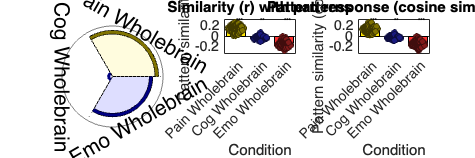

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)
set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');

title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)
set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

## Vicarious > (Pain & Cognitive)

clear all

#### Vicarious > PC :: load dataset

contrast_of_interest = 'stim_V';

nifti_save_dir = '/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model02_CESO/2ndlevel';
nifti_save_fname_prefix = 'model02-CESO_epoch-stim';

mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESO/1stlevel';

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 38736756 bytes
Loading image number:    97
Elapsed time is 3.235340 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 9174036  Bit rate: 23.13 bits


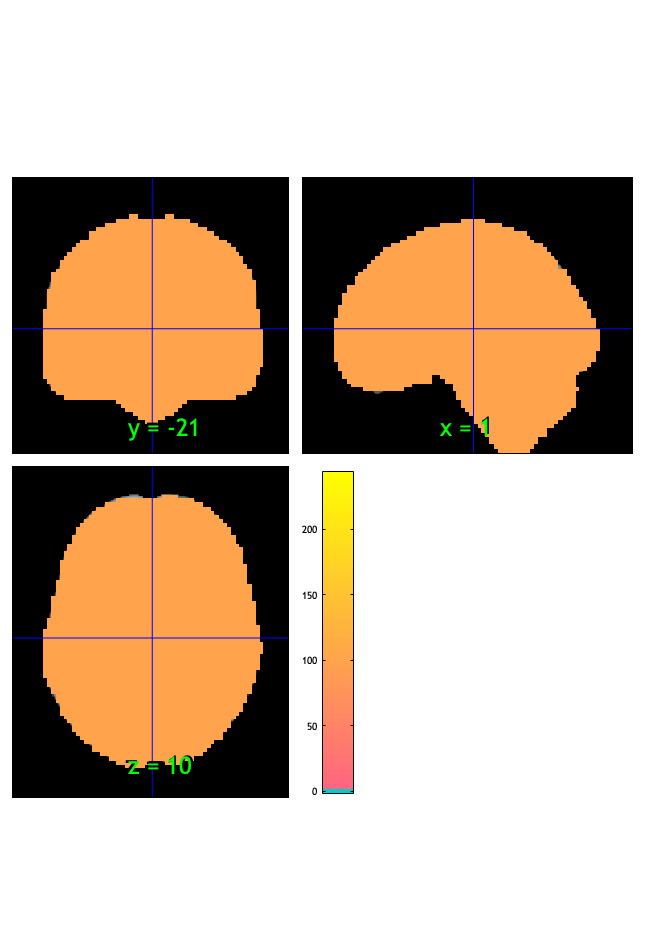

SPM12: spm_check_registration (v7759)              23:26:11 - 21/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C', ...

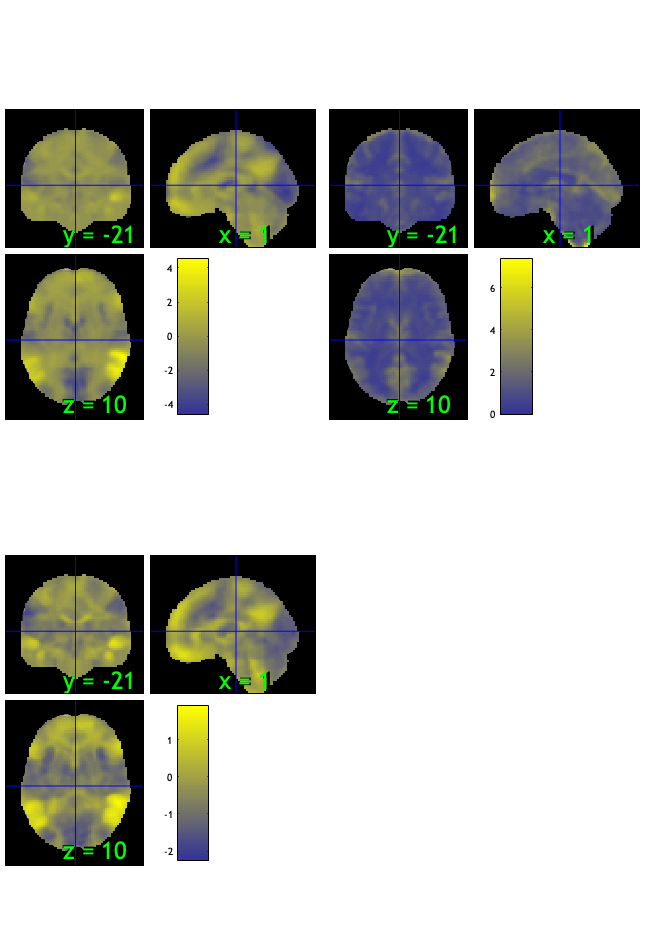

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 2 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 37.11%
Expected 4.85 outside 95% ellipsoid, found   7

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 2 images		Cases 23 24 
Uncorrected: 7 images		Cases 1 9 11 23 24 33 81 

Retained 6 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 43.30%
Expected 4.85 outside 95% ellipsoid, found   7

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 7 images		Cases 3 11 24 33 54 63 68 

Mahalanobis (cov and corr, q<0.05 corrected):
  2 images 
                               Outlier_count    Percentage
                    

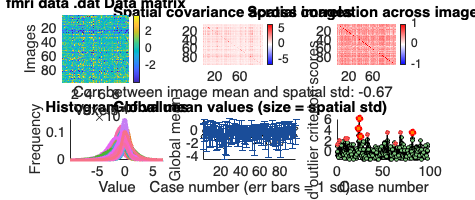

SPM12: spm_check_registration (v7759)              23:26:43 - 21/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

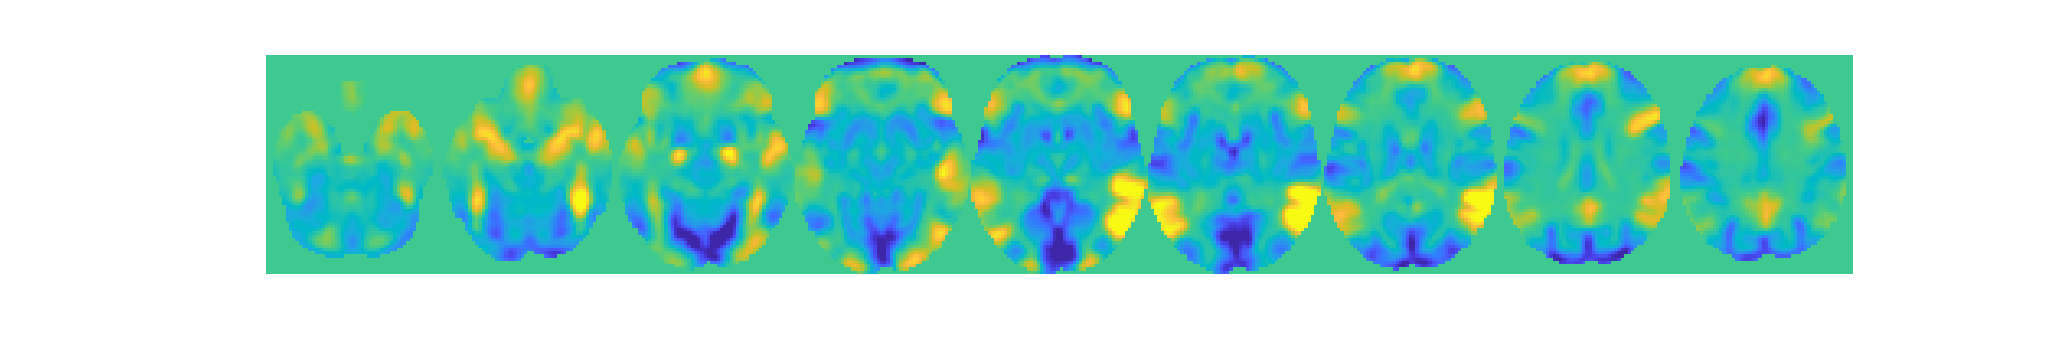

wh_outlier_uncorr = 97×1 logical array
   1
   0
   1
   0
   0
   0
   0
   0
   1
   0


wh_outlier_corr = 97×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


    'simple_stim_P', 'simple_stim_V', 'simple_stim_C'
};

index = find(strcmp(contrast_name, contrast_of_interest));

con_name = sprintf('*con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

#### Vicarious > PC :: `check data coverage`

m = mean(con_data_obj);

current length is 97


m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

#### Vicarious > PC :: Plot diagnostics, before l2norm

drawnow; snapnow


con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×93 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [93×21 char]
              fullpath: [97×112 char]
           files_exist: [97×1 logical]
               history:

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×93 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [93×21 char]
              fullpath: [93×112 char]
           files_exist: [97×1 logical]
               history:

#### Vicarious > PC :: run robfit

set(gcf,'Visible','on')

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×93 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [93×21 char]
              fullpath: [93×112 char]
           files_exist: [93×1 logical]
               history:

figure ('Visible', 'on');
drawnow, snapnow;

after removing 4 participants, size is now 93


#### Vicarious > PC :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))))
%for s = 1:length(wh_outlier_corr)
  %  disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:)
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:)
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:)
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

#### Vicarious > PC :: plot diagnostics, after l2norm

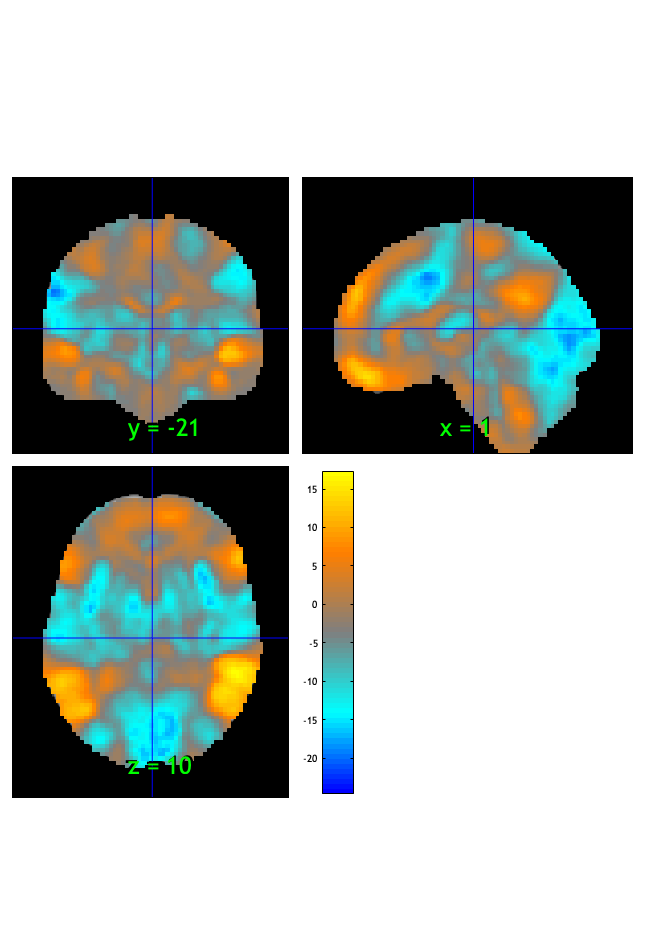

One-sample t-test
Calculating t-statistics and p-values


SPM12: spm_check_registration (v7759)              23:26:47 - 21/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Image   1 FDR q < 0.050 threshold is 0.038450

Image   1
 13 contig. clusters, sizes   1 to 76754
Positive effect: 20309 voxels, min p-value: 0.00000000
Negative effect: 56486 voxels, min p-value: 0.00000000


SPM12: spm_check_registration (v7759)              23:26:49 - 21/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


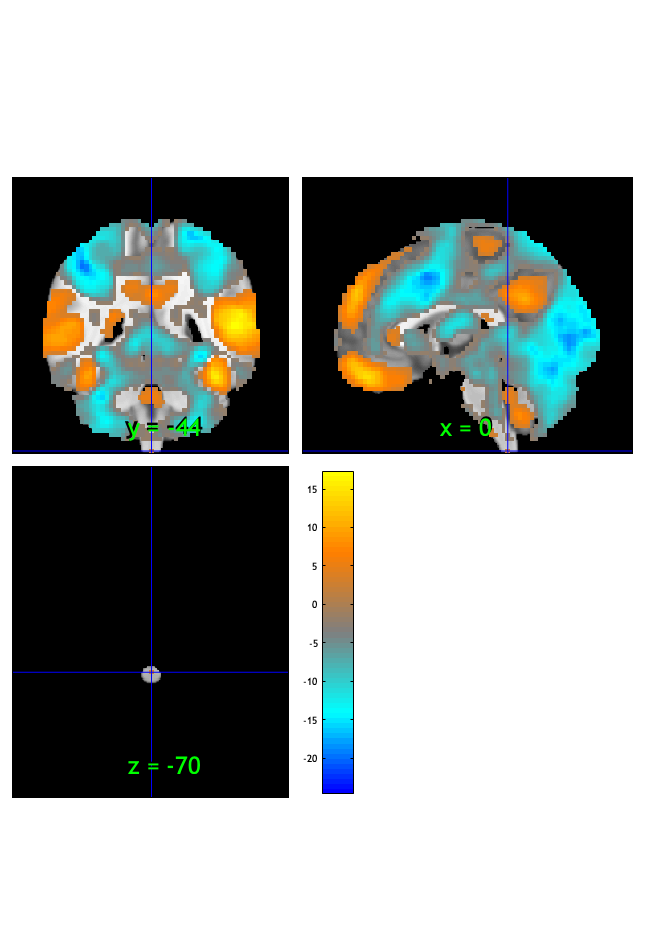

Image   1 FDR q < 0.001 threshold is 0.000626

Image   1
 12 contig. clusters, sizes   1 to 58759
Positive effect: 15122 voxels, min p-value: 0.00000000
Negative effect: 47363 voxels, min p-value: 0.00000000


SPM12: spm_check_registration (v7759)              23:26:50 - 21/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


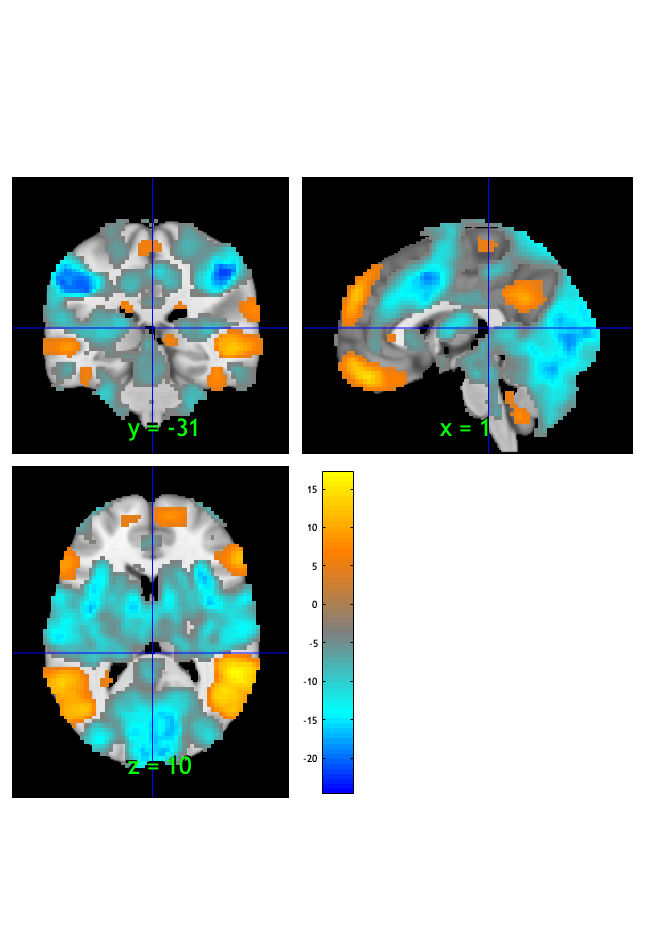

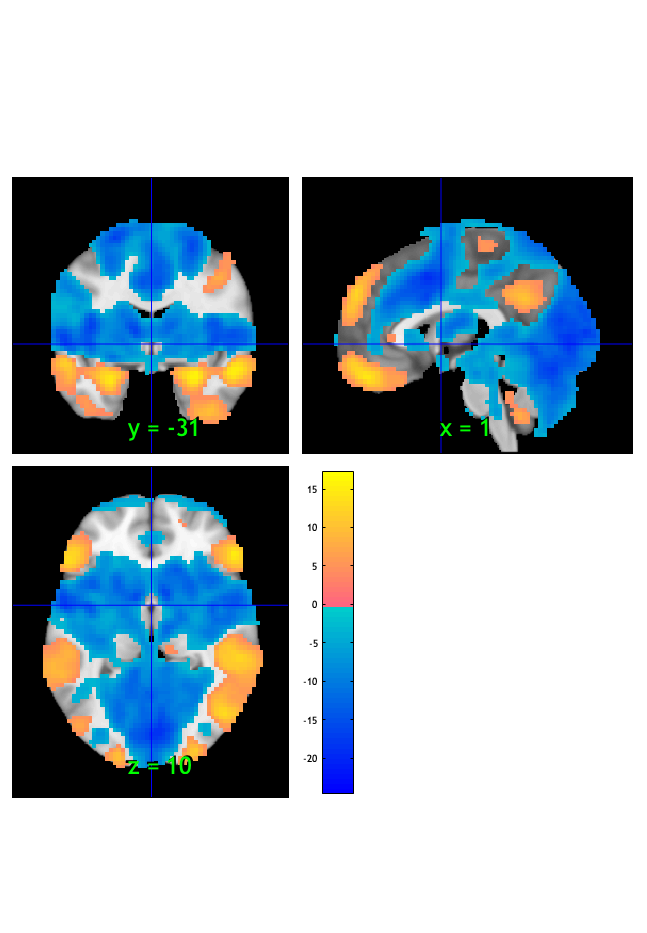

Setting up fmridisplay objects
sagittal montage: 1622 voxels displayed, 60863 not displayed on these slices
sagittal montage: 1662 voxels displayed, 60823 not displayed on these slices
sagittal montage: 1562 voxels displayed, 60923 not displayed on these slices
axial montage: 11507 voxels displayed, 50978 not displayed on these slices
axial montage: 12455 voxels displayed, 50030 not displayed on these slices


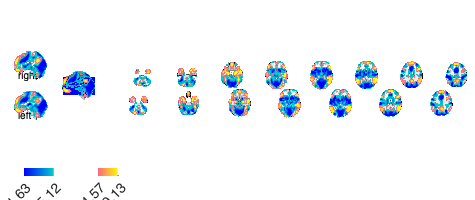

Writing: 
/Users/h/Desktop/stim_V_fdr_t.nii


imgs2 = con.rescale('l2norm_images');

#### Vicarious > PC :: ttest

t = ttest(imgs2);

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low        words_low        testr_high      words_high   
    _________    _________________    __________    _______________

    -0.25143     {'motor'        }     0.36617      {'social'     }
     -0.2248     {'spatial'      }     0.30835      {'face'       }
    -0.21301     {'finger'       }         0.3      {'emotion'    }
     -0.2079     {'imagery'      }     0.28832      {'faces'      }
    -0.20189     {'somatosensory'}     0.28456      {'facial'     }
     -0.2005     {'execution'    }     0.27858      {'expression' }
    -0.20032     {'tactile'      }     0.26634      {'expressions'}
    -0.19435     {'sensorimotor' }     0.26588      {'person'     }
    -0.19008     {'movements'    }     0.25768      {'story'      }
     -0.1895

orthviews(t);
drawnow, snapnow;


Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii
/Users/h/Documents/MATLAB

fdr_t05 = threshold(t, .05, 'fdr');
orthviews(fdr_t05);
drawnow, snapnow;
fdr_t05.dat = fdr_t05.dat.*fdr_t05.sig
write(fdr_t05, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-05.nii')), 'overwrite');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.1386	-25.2982	0.0000	1.0000	
Cog Wholebrain	0.0193	6.4932	0.0000	1.0000	
Emo Wholebrain	0.1139	21.7580	0.0000	1.0000	
 



fdr_t001 = threshold(t, .001, 'fdr');
orthviews(fdr_t001);
drawnow, snapnow;
fdr_t001.dat = fdr_t001.dat.*fdr_t001.sig

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}     -0.13862     0.0054048    -25.648    2.2204e-15    -2.6041 
    {'Cog Wholebrain' }      0.01927     0.0029669     6.4949    3.6718e-09    0.65946 
    {'Emo Wholebrain' }      0.11394     0.0052014     21.906    2.2204e-15     2.2242 



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {97×3 cell}
        text_han: {97×3 cell}
       point_han: {97×3 cell}
    star_handles: [24.0009 25.0005 26.0005]


write(fdr_t001, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-001.nii')), 'overwrite');

create_figure('montage'); axis off;
montage(fdr_t001);
drawnow, snapnow;

#### Vicarious > PC :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');
% [image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( m, 'images_are_replicates', false, 'noverbose');

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83

**Vicarious > PC :: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');
bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}     -0.13477     0.0054598    -24.685    2.2204e-15    -2.5064 
    {'Cog Wholebrain' }     0.018011     0.0028476      6.325    8.0113e-09     0.6422 
    {'Emo Wholebrain' }      0.11253     0.0051793     21.728    2.2204e-15     2.2061 



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {97×3 cell}
        text_han: {97×3 cell}
       point_han: {97×3 cell}
    star_handles: [32.0004 33.0005 34.0004]


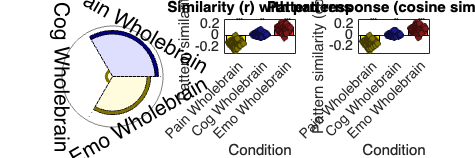

create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)
set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)
set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

## Cognitive > (Pain & Vicarious)

#### Cognitive > PV :: load dataset

contrast_of_interest = 'stim_C';

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 38736756 bytes
Loading image number:    97
Elapsed time is 3.476793 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 9208457  Bit rate: 23.13 bits



nifti_save_dir = '/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model02_CESO/2ndlevel';
nifti_save_fname_prefix = 'model02-CESO_epoch-stim';


SPM12: spm_check_registration (v7759)              23:27:44 - 21/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


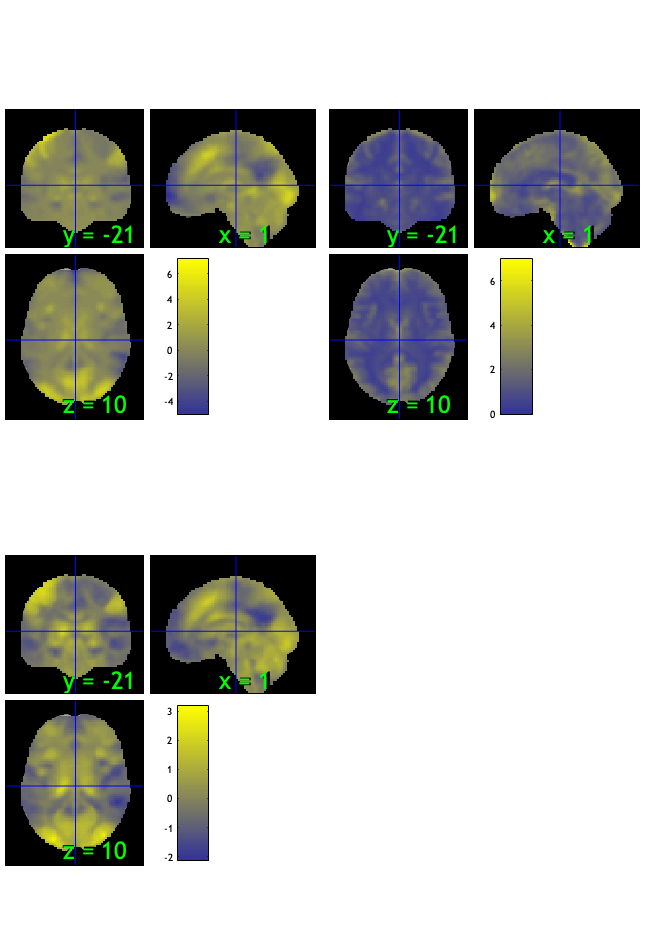

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 2 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 47.42%
Expected 4.85 outside 95% ellipsoid, found   5

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 5 images		Cases 23 25 35 81 97 

Retained 6 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 42.27%
Expected 4.85 outside 95% ellipsoid, found   8

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 8 images		Cases 11 24 39 42 65 66 69 73 

Mahalanobis (cov and corr, q<0.05 corrected):
  0 images 
                               Outlier_count    Percentage
                         

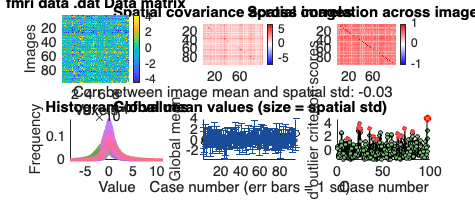

SPM12: spm_check_registration (v7759)              23:28:14 - 21/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

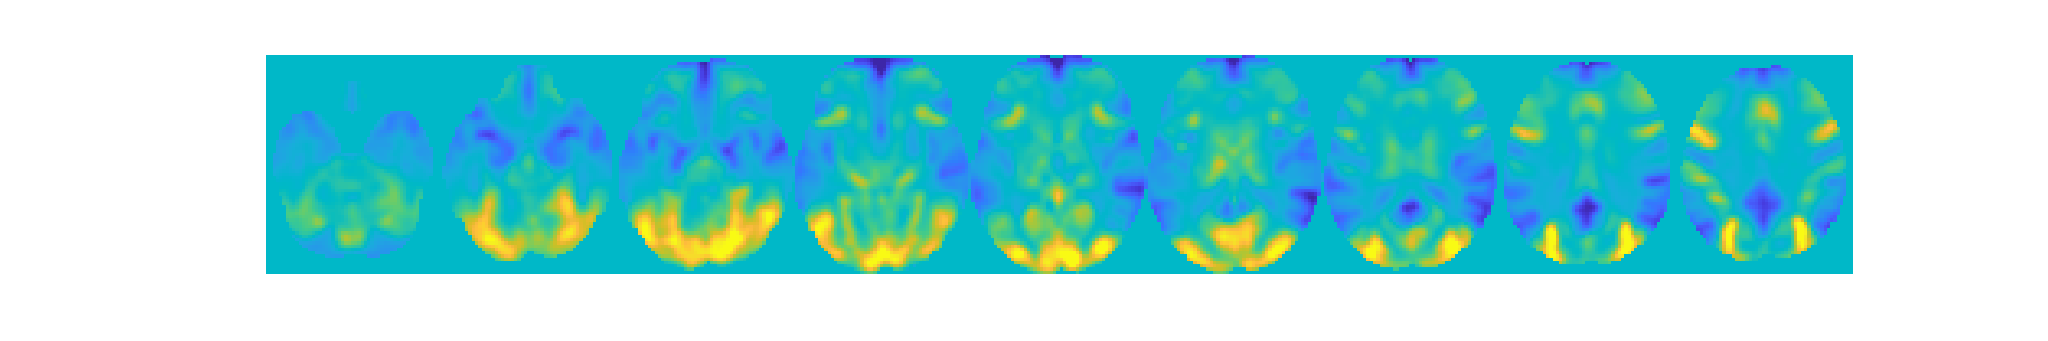

wh_outlier_uncorr = 97×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


wh_outlier_corr = 97×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESO/1stlevel';
contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'motor', ...

    'simple_cue_P', 'simple_cue_V', 'simple_cue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C'
};

index = find(strcmp(contrast_name, contrast_of_interest));
con_name = sprintf('*con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));

current length is 97


spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×96 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [96×21 char]
              fullpath: [97×112 char]
           files_exist: [97×1 logical]
               history:

#### Cognitive > PV :: `check data coverage`

m = mean(con_data_obj);

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×96 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [96×21 char]
              fullpath: [96×112 char]
           files_exist: [97×1 logical]
               history:

m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×96 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [96×21 char]
              fullpath: [96×112 char]
           files_exist: [96×1 logical]
               history:

orthviews(m, 'trans') % display

#### Cognitive > PV :: Plot diagnostics, before l2norm

drawnow; snapnow

after removing 1 participants, size is now 96



[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj)

#### Cognitive > PV :: run robfit

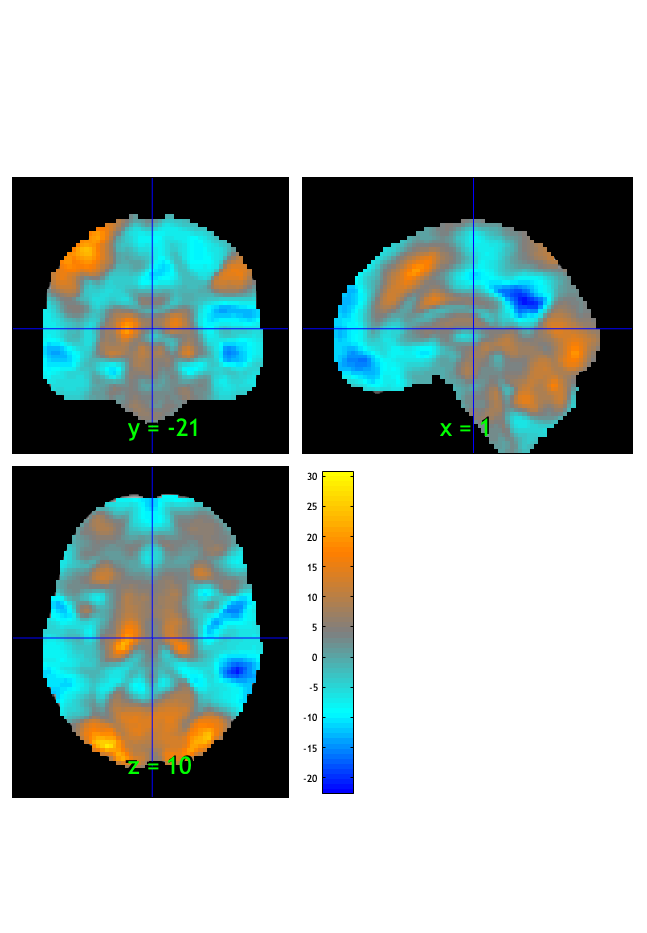

One-sample t-test
Calculating t-statistics and p-values


SPM12: spm_check_registration (v7759)              23:28:18 - 21/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Image   1 FDR q < 0.050 threshold is 0.039307

Image   1
 11 contig. clusters, sizes   1 to 78465
Positive effect: 43035 voxels, min p-value: 0.00000000
Negative effect: 35456 voxels, min p-value: 0.00000000


SPM12: spm_check_registration (v7759)              23:28:19 - 21/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


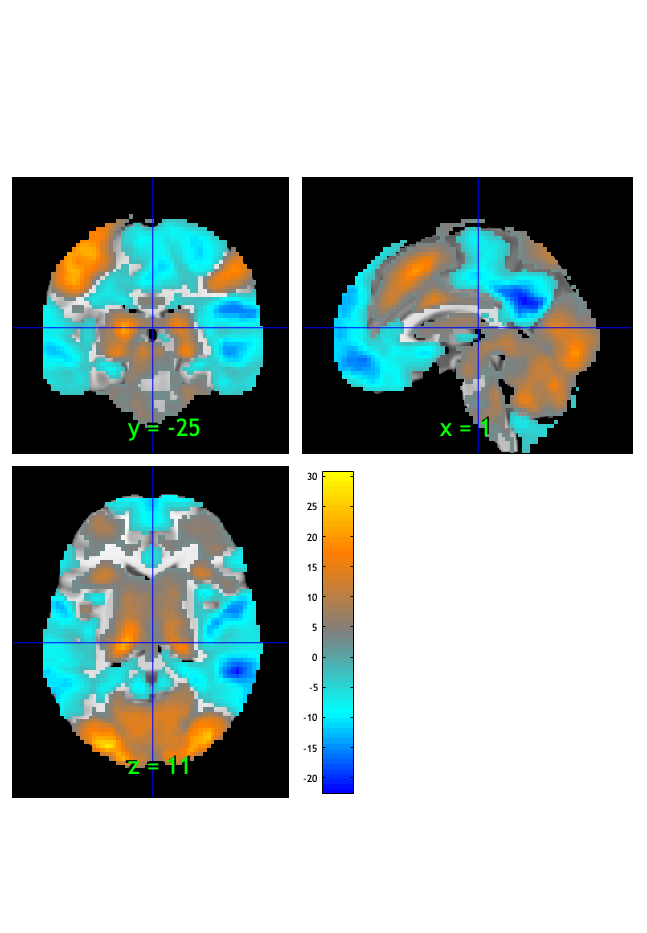

Image   1 FDR q < 0.001 threshold is 0.000649

Image   1
  8 contig. clusters, sizes   1 to 64733
Positive effect: 35684 voxels, min p-value: 0.00000000
Negative effect: 29136 voxels, min p-value: 0.00000000


SPM12: spm_check_registration (v7759)              23:28:20 - 21/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


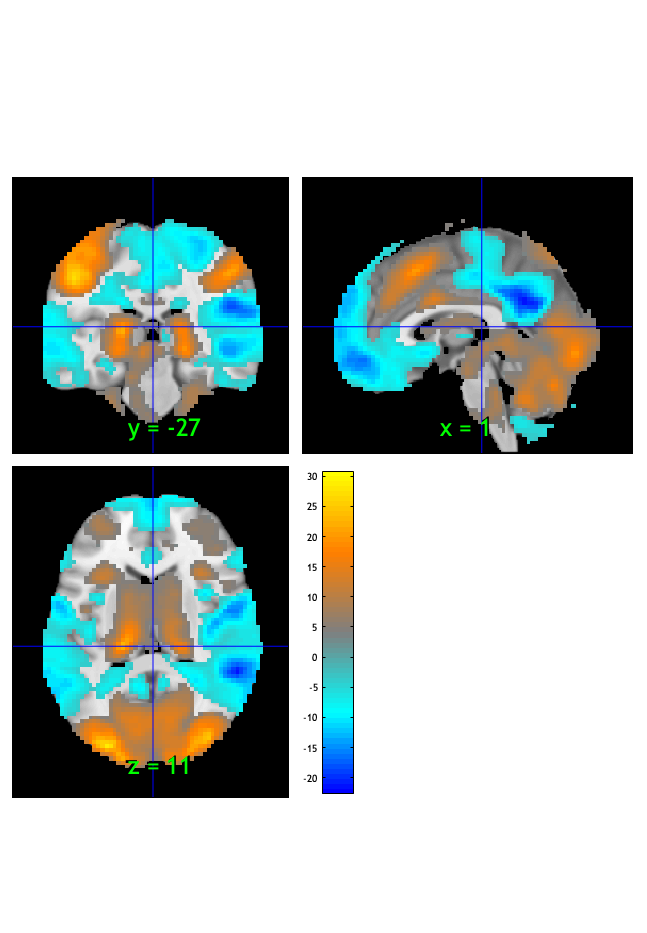

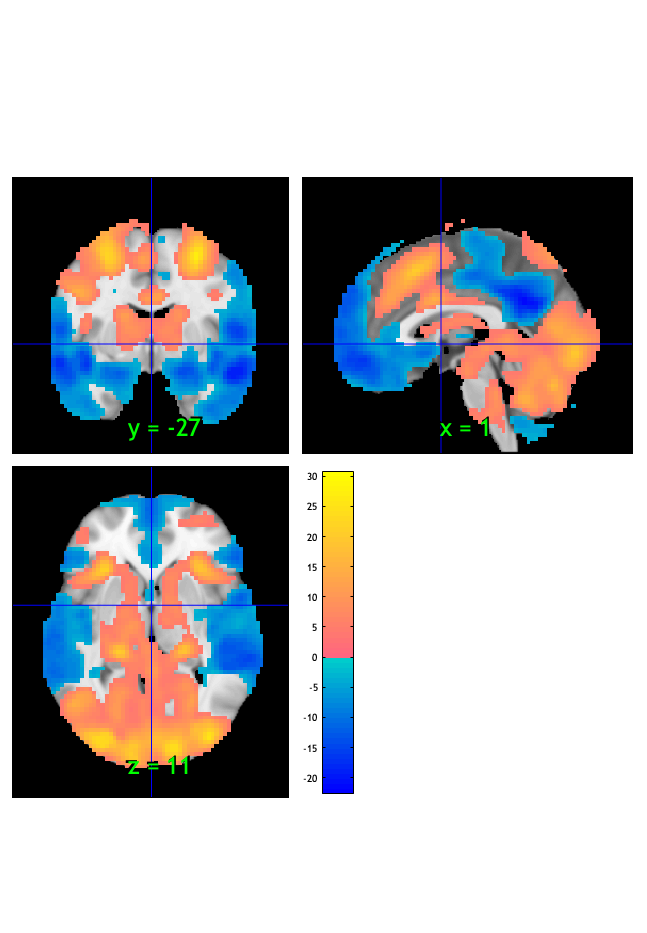

Setting up fmridisplay objects
sagittal montage: 1629 voxels displayed, 63191 not displayed on these slices
sagittal montage: 1555 voxels displayed, 63265 not displayed on these slices
sagittal montage: 1599 voxels displayed, 63221 not displayed on these slices
axial montage: 12121 voxels displayed, 52699 not displayed on these slices
axial montage: 13297 voxels displayed, 51523 not displayed on these slices


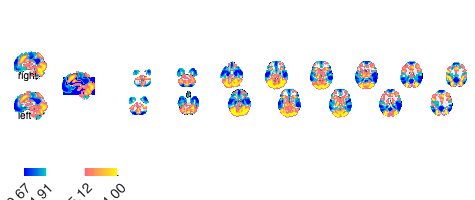

Writing: 
/Users/h/Desktop/stim_C_fdr_t.nii


set(gcf,'Visible','on')

figure ('Visible', 'on');
drawnow, snapnow;

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low      words_low      testr_high       words_high   
    _________    _____________    __________    ________________

    -0.34305     {'rating'   }     0.46652      {'visual'      }
    -0.31935     {'trait'    }     0.35009      {'shape'       }
    -0.31831     {'social'   }     0.33732      {'object'      }
    -0.31789     {'emotion'  }     0.32946      {'attention'   }
    -0.31228     {'affect'   }      0.3198      {'eye'         }
    -0.30644     {'person'   }     0.31773      {'letter'      }
    -0.29705     {'negative' }      0.3119      {'visuospatial'}
    -0.29634     {'affective'}      0.3044      {'objects'     }
     -0.2961     {'positive' }     0.30417      {'color'       }
    -0.29497     {'ratings'  }     0.29935   

#### Cognitive > PV :: remove outliers based on plot

con = con_data_obj;

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii
/Users/h/Documents/MATLAB

disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))))
%for s = 1:length(wh_outlier_corr)
   % disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:)

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.0463	-13.5772	0.0000	1.0000	
Cog Wholebrain	0.0003	0.1061	0.9157	0.0000	
Emo Wholebrain	0.0436	12.7130	0.0000	1.0000	
 


con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:)
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:)
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

#### Cognitive > PV:: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}    -0.046288     0.0034043    -13.597    2.2204e-15     -1.3806
    {'Cog Wholebrain' }    0.0002878     0.0027086    0.10625        0.9156    0.010788
    {'Emo Wholebrain' }     0.043553     0.0034223     12.726    2.2204e-15      1.2922



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {97×3 cell}
        text_han: {97×3 cell}
       point_han: {97×3 cell}
    star_handles: [24.0010 25.0006 26.0006]


#### Cognitive > PV :: ttest

t = ttest(imgs2);
orthviews(t);
drawnow, snapnow;

fdr_t05 = threshold(t, .05, 'fdr');
orthviews(fdr_t05);
drawnow, snapnow;
fdr_t05.dat = fdr_t05.dat.*fdr_t05.sig
write(fdr_t05, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-05.nii')), 'overwrite');

fdr_t001 = threshold(t, .001, 'fdr');
orthviews(fdr_t001);

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83

drawnow, snapnow;
fdr_t001.dat = fdr_t001.dat.*fdr_t001.sig
write(fdr_t001, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-001.nii')), 'overwrite');


Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}    -0.044558     0.0033694    -13.225    2.2204e-15     -1.3427
    {'Cog Wholebrain' }    0.0015149     0.0026055    0.58143       0.56231    0.059036
    {'Emo Wholebrain' }     0.041295     0.0033627      12.28    2.2204e-15      1.2469



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {97×3 cell}
        text_han: {97×3 cell}
       point_han: {97×3 cell}
    star_handles: [32.0005 33.0006 34.0005]


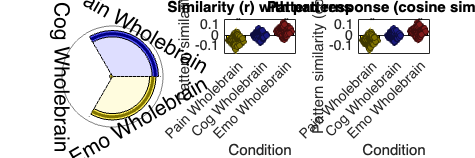

create_figure('montage'); axis off;
montage(fdr_t001);
drawnow, snapnow;

#### Cognitive > PV :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');
% [image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( m, 'images_are_replicates', false, 'noverbose');

**Cognitive > PV :: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');
bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');
axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)
set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')


Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 38736756 bytes
Loading image number:    97
Elapsed time is 3.945606 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 9179484  Bit rate: 23.13 bits


test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

SPM12: spm_check_registration (v7759)              23:29:02 - 21/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


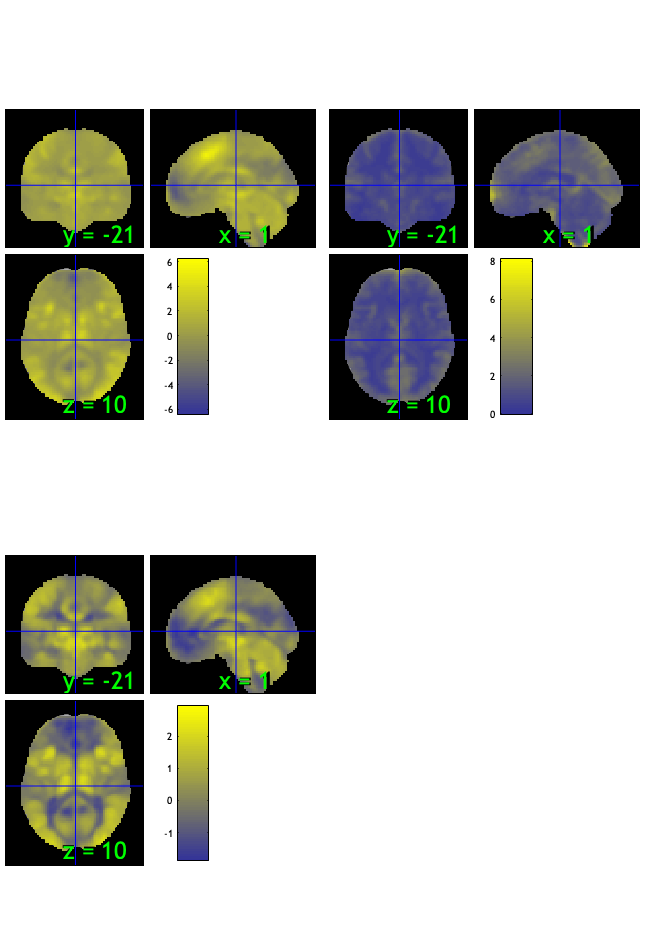

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 2 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 37.11%
Expected 4.85 outside 95% ellipsoid, found   4

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 2 images		Cases 23 24 
Uncorrected: 4 images		Cases 1 9 23 24 

Retained 12 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 42.27%
Expected 4.85 outside 95% ellipsoid, found   6

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 3 
Uncorrected: 6 images		Cases 3 12 54 69 80 92 

Mahalanobis (cov and corr, q<0.05 corrected):
  3 images 
                               Outlier_count    Percentage
                              

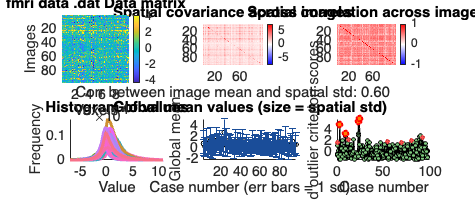

SPM12: spm_check_registration (v7759)              23:29:33 - 21/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

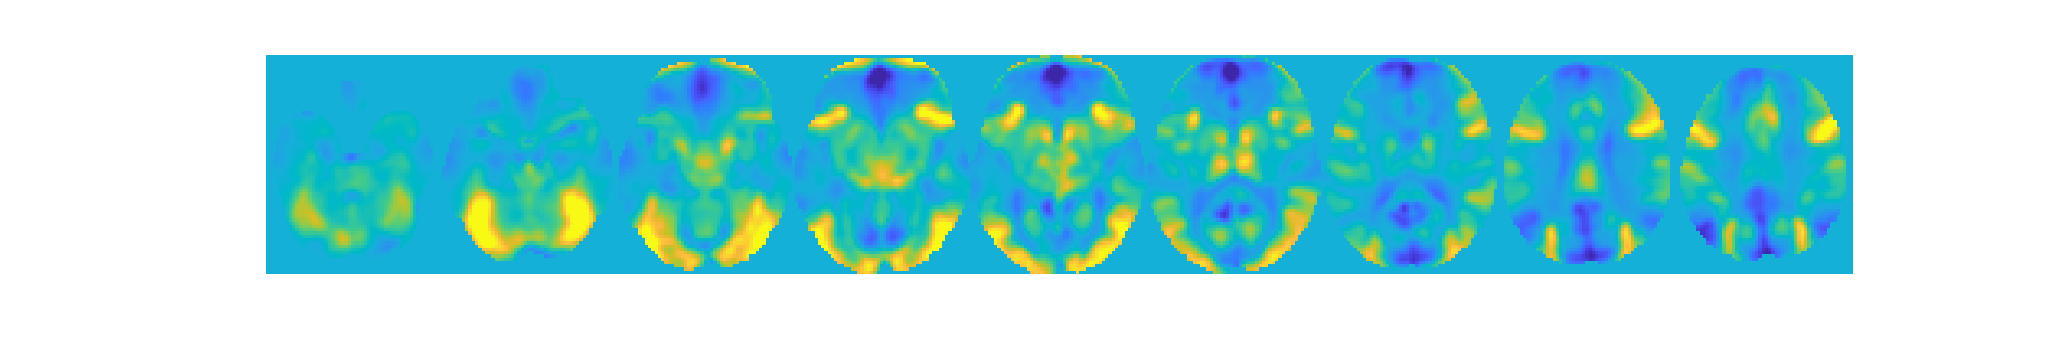

wh_outlier_uncorr = 97×1 logical array
   1
   0
   1
   0
   0
   0
   0
   0
   1
   0


wh_outlier_corr = 97×1 logical array
   0
   0
   1
   0
   0
   0
   0
   0
   1
   0



    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)
set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

current length is 97


## Domain General

#### General :: load dataset

contrast_of_interest = 'stim_G';


con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×93 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [93×21 char]
              fullpath: [97×112 char]
           files_exist: [97×1 logical]
               history:

mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model02_CESO/1stlevel';

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×93 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [93×21 char]
              fullpath: [93×112 char]
           files_exist: [97×1 logical]
               history:

contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×93 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [93×21 char]
              fullpath: [93×112 char]
           files_exist: [93×1 logical]
               history:

    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'motor', ...

after removing 4 participants, size is now 93


    'simple_cue_P', 'simple_cue_V', 'simple_cue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C'
};


One-sample t-test
Calculating t-statistics and p-values


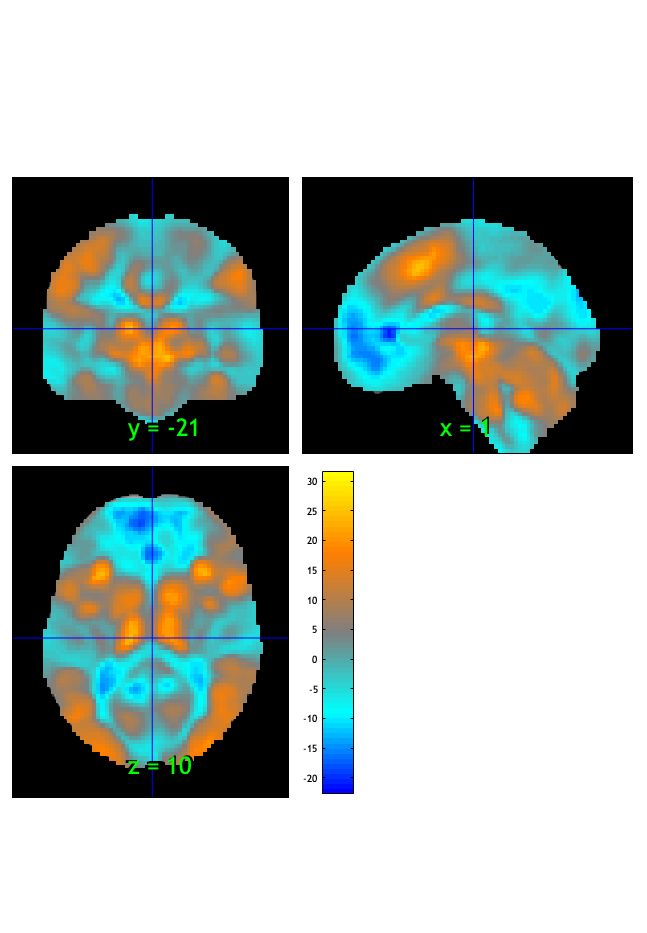

SPM12: spm_check_registration (v7759)              23:29:37 - 21/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


index = find(strcmp(contrast_name, contrast_of_interest));

con_name = sprintf('*con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));
spm('Defaults','fMRI') 

Image   1 FDR q < 0.050 threshold is 0.039297

Image   1
  6 contig. clusters, sizes   1 to 78450
Positive effect: 51505 voxels, min p-value: 0.00000000
Negative effect: 26967 voxels, min p-value: 0.00000000


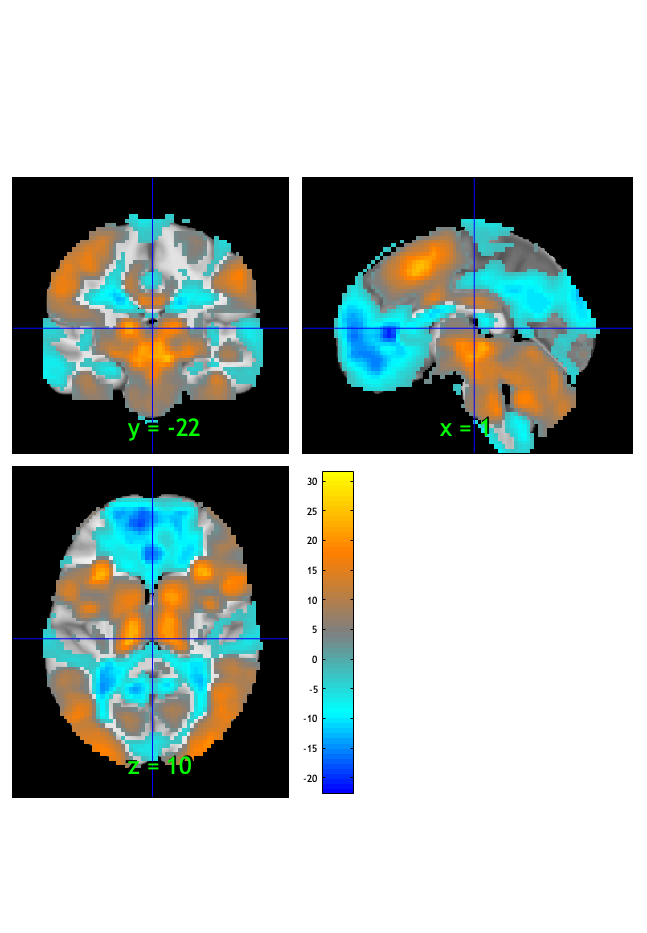

SPM12: spm_check_registration (v7759)              23:29:38 - 21/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


con_fldr = {con_list.folder}; fname = {con_list.name};

con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

#### General :: `check data coverage`

m = mean(con_data_obj);

Image   1 FDR q < 0.001 threshold is 0.000655

Image   1
 23 contig. clusters, sizes   1 to 64934
Positive effect: 44568 voxels, min p-value: 0.00000000
Negative effect: 20884 voxels, min p-value: 0.00000000


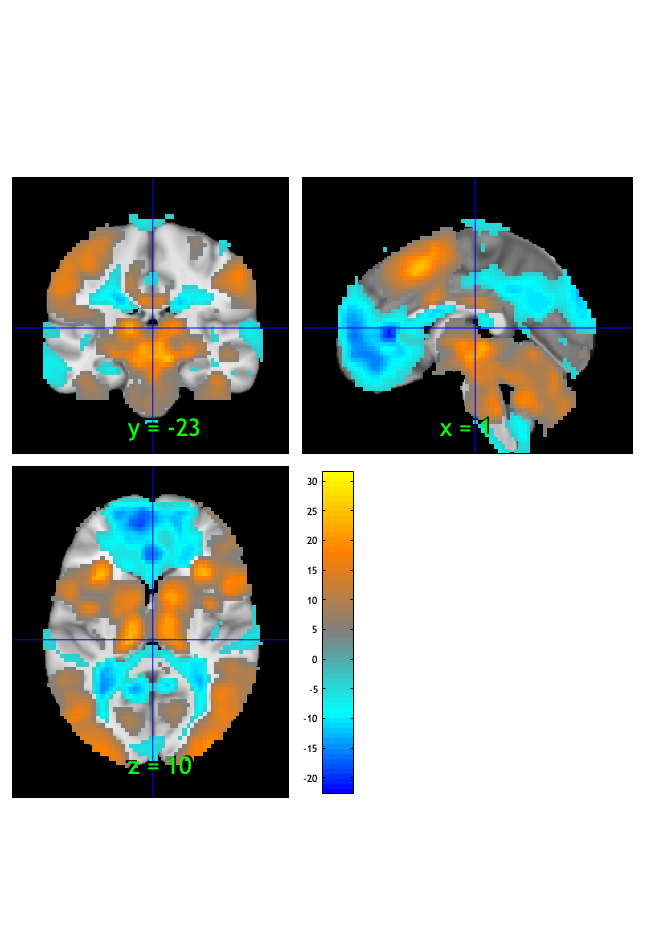

SPM12: spm_check_registration (v7759)              23:29:39 - 21/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


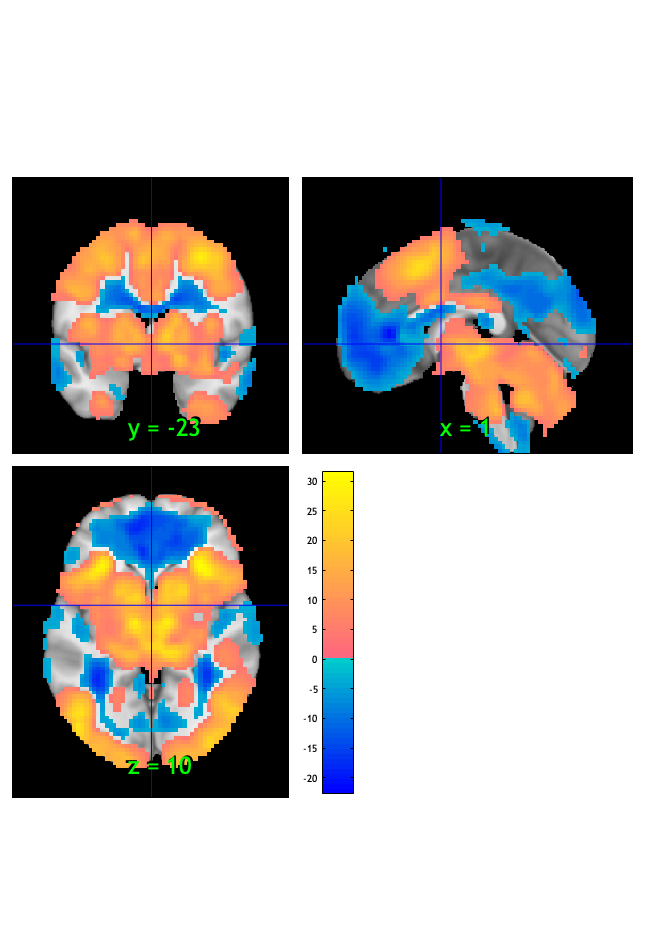

m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);

orthviews(m, 'trans') % display

#### General :: Plot diagnostics, before l2norm

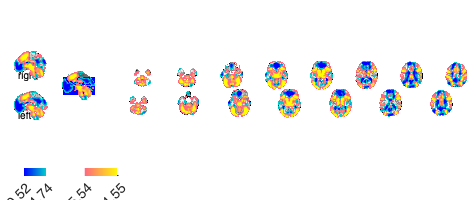

Setting up fmridisplay objects
sagittal montage: 1714 voxels displayed, 63738 not displayed on these slices
sagittal montage: 1681 voxels displayed, 63771 not displayed on these slices
sagittal montage: 1660 voxels displayed, 63792 not displayed on these slices
axial montage: 12336 voxels displayed, 53116 not displayed on these slices
axial montage: 13523 voxels displayed, 51929 not displayed on these slices


drawnow; snapnow


[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj)

#### Cognitive > PV :: run robfit

set(gcf,'Visible','on')

Writing: 
/Users/h/Desktop/stim_G_fdr_t.nii


figure ('Visible', 'on');
drawnow, snapnow;

#### General:: remove outliers based on plot

con = con_data_obj;

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low      words_low       testr_high       words_high   
    _________    ______________    __________    ________________

    -0.38623     {'trait'     }     0.38386      {'visual'      }
    -0.36608     {'age'       }     0.27557      {'execution'   }
    -0.35967     {'personal'  }     0.27387      {'object'      }
    -0.32761     {'person'    }      0.2587      {'gesture'     }
    -0.32367     {'self'      }     0.25431      {'movements'   }
    -0.31947     {'positive'  }     0.25348      {'mirror'      }
    -0.31233     {'default'   }     0.25149      {'maintenance' }
    -0.30398     {'depression'}     0.25066      {'letter'      }
    -0.30357     {'disorder'  }     0.24572      {'orthographic'}
    -0.30184     {'negative'  }   

disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))))
%for s = 1:length(wh_outlier_corr)
   % disp(strcat("-------subject", num2str(s), "------"))

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii
/Users/h/Documents/MATLAB

con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:)
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:)
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:)
%end

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.0451	-10.0259	0.0000	1.0000	
Cog Wholebrain	-0.0491	-18.7749	0.0000	1.0000	
Emo Wholebrain	0.0867	18.9527	0.0000	1.0000	
 


disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

#### General:: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### General :: ttest

t = ttest(imgs2);

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}    -0.045104     0.0044923     -10.04    2.2204e-15    -1.0194 
    {'Cog Wholebrain' }    -0.049141     0.0026126    -18.809    2.2204e-15    -1.9098 
    {'Emo Wholebrain' }     0.086702     0.0045497     19.057    2.2204e-15     1.9349 



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {97×3 cell}
        text_han: {97×3 cell}
       point_han: {97×3 cell}
    star_handles: [24.0011 25.0007 26.0007]


orthviews(t);
drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');
orthviews(fdr_t);
drawnow, snapnow;

fdr_t = threshold(t, .001, 'fdr');
orthviews(fdr_t);
drawnow, snapnow;

create_figure('montage'); axis off;

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83

montage(fdr_t);
drawnow, snapnow;
write(fdr_t, 'fname', strcat('/Users/h/Desktop/', contrast_of_interest, '_fdr_t.nii'), 'overwrite');


Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}    -0.042243     0.0043885    -9.6259    2.2204e-15    -0.97736
    {'Cog Wholebrain' }     -0.04542     0.0025641    -17.714    2.2204e-15     -1.7986
    {'Emo Wholebrain' }     0.082318     0.0046141     17.841    2.2204e-15      1.8115



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {97×3 cell}
        text_han: {97×3 cell}
       point_han: {97×3 cell}
    star_handles: [32.0006 33.0007 34.0006]


#### General :: Neurosynth similarity

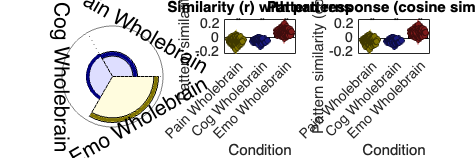

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');
% [image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( m, 'images_are_replicates', false, 'noverbose');

**General :: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');
bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');
axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)
set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)
set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')